% clc;
% clear;

## 子文件夹

addpath("import\");
addpath("plot\");

## 材料参数

density=2.7*10^3;
mu=26.1*10^9;

## 入射设置

nff = 10;
ff = linspace(2e6,4e6,nff);
% %{
nff = 1;
ff = 1e6;
%}
mode_in = 2;
% 散射系数
cR = cell(nff,1);
cT = cell(nff,1);

## 几何参数

W=1*10^(-3); % 板厚
b = W/2; % 半板厚
h=1;

## 网格节点坐标

边界分为20个单元，轴向分为80个单元；长度[-7.5mm,7.5mm]，宽度[-0.5mm,0.5mm].

fileName = 'pipe';
[Nnode, Nelement, Coordinate, Ielement,dL,dW] = read_mesh_info_CQUAD8([fileName '.dat']);
Coordinate = Coordinate/b;

## 边界信息

fileNameMPHTXT = [fileName '.mphtxt'];
bnd_top = read_boudary_info(fileNameMPHTXT,"bnd_top");
bnd_bottom = read_boudary_info(fileNameMPHTXT,"bnd_bottom");
nLeft = read_boudary_info(fileNameMPHTXT,"bnd_left");
nRight = read_boudary_info(fileNameMPHTXT,"bnd_right");
nMid = 1:Nnode; 
nMid([nLeft;nRight])=[]; % 中间边界节点的行号

% 将边界节点排序
refPoint = [0;-2*W/b];
nLeft = order_bnd(refPoint,Coordinate, nLeft);
nRight = order_bnd(refPoint,Coordinate, nRight);

## 缺陷定义

L_crack = 2*b;
W_crack = 0.2*b;
bnd_crack = crack_boundary(Coordinate,L_crack,W_crack,b);
% bnd_crack = tr_crack_boundary(Coordinate,L_crack,W_crack,b);
bnd_crack_e =  bound_element(Ielement, bnd_crack);

## 刚度矩阵

[ K,M ] = Stiffness_Mass_matrix( Nnode,Nelement,Ielement,Coordinate,mu,density,b );
% Cf = 2*pi*ff;
% K = (K-Cf^2*M)/mu;
[D] = Stiffness_Changed_Position(nLeft,nMid,nRight,K);
[l,m,r] = Stiffness_Changed_Position(nLeft,nMid,nRight);

## 边界条件

u = nan(Nnode,1);
F = zeros(Nnode,1);

二类边界条件

F(r)=1e5;

一类边界条件

F(l)=-1;
D(l,l)=eye(length(l));
D(l,[m r])=0;

## 求解

u = D\F;

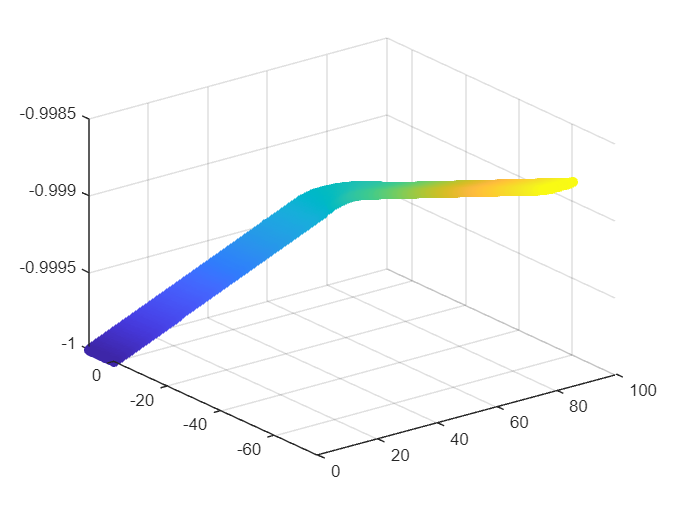

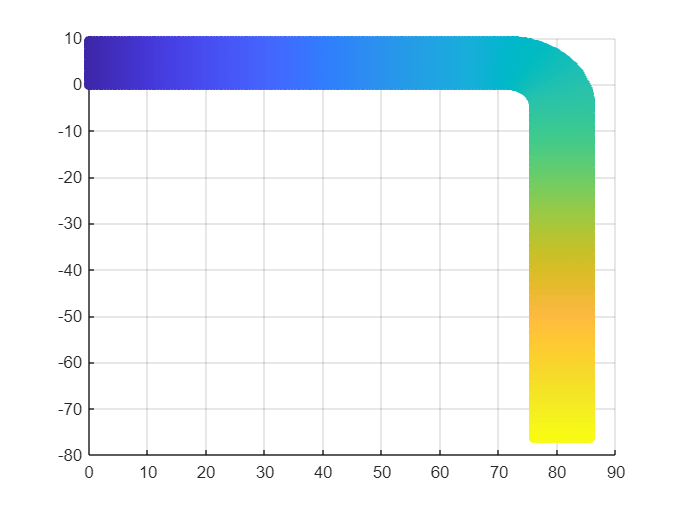

run draw_displacement.mlx